# Mess- und Regelungstechnik - Praktikum 5

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Vorbereitung

In diesem Praktikum verwenden Sie erstmals Simulink, MATLABs Toolbox zur Simulation von dynamischen Systemen. Für das Praktikum wird die "Simscape" Toolbox benötigt.

Starten Sie Simulink entweder vom Menü "Home" oder mit dem Befehl `simulink`.

Öffnen Sie ein neues "Blank Model".

Sie können nun nach belieben sog. "Blocks" hinzufügen, indem Sie auf der freien Fläche eine Bezeichnung (bspw. *"Resistor"*) über die Tastatur eingeben. Mit der Maus können Blöcke positioniert und verbunden werden. Per Doppelklick können Sie einzelne Blöcke konfigurieren. Eine ausfühlichere Anleitung zum Umgang mit Simulink finden Sie im Moodle-Kurs ("00_Simulink_und_Matlab.pdf

"). 

## Aufgabe 1

### 1)

Bauen Sie die Messschaltung entsprechend Abb. 1 auf.

*Hinweis: Es wurden die elektronischen Bauteile "DC Voltage Source", "Resistor", "Electrical Reference" und "Voltage Sensor" und die Simulink-Komponenten "Solver Configuration", "PS-Simulink-Converter" und "Scope" verwendet.*

*Tipp: Sie können Blöcke mit Strg+R rotieren und Strg+I spiegeln.*

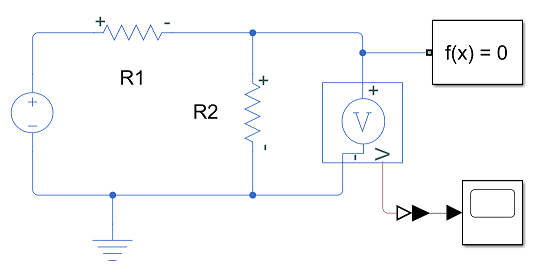

Abbildung 1: Schaltung mit zwei Widerständen

### 2)

Stellen Sie bei der Spannungsquelle eine Spannung von $1V$ und bei R1 und R2 einen Widerstand von $1k\Omega$ bzw. $470\Omega$ ein.

### 3)

Starten Sie die Simulation mit dem grünen "Run"-Button. Betrachten Sie die Messung des Spannugsmessgeräts, indem Sie das Menü des Scopes öffnen und beurteilen Sie den Streckentyp der Schaltung.

Streckentyp: linear, hat eine proportionalen Zusammenhang zwischen Ein- und Ausgang 

Eingang = Sprungfunkion (mit Höhe 1),

Ausgang = Sprungfunktion (mit Höhe  0.32) 

Veränderung nur um Faktor 0.32

### 4)

Bestimme Sie die Parameter für den ausgewählten Typ der Strecke zum einen anhand der gemessenen Sprungantwort und zum anderen rechnerisch mithilfe der Gleichungen, die Sie aus den Grundlagen der Elektrotechnik kennen ("06_Modellbildung_1", S. 19,20). Bringen Sie dazu die Gleichung in die Form der Formeln des P-, PT1- oder PT2-Gliedes aus der Vorlesung (siehe. S. 11, 15, 20 "08_Verhalten_und_Analyse_1").

**P-Glied:**

0 = u - uR1 - uR2

uR2 = y

uR1 = u * R1 / (R1 + R2) 

0 = u - u * R1 / (R1 + R2)  -  y

uR2 = R2  / (R1 + R2) * u

kp = R2  / (R1 + R2)

0 = u - uR1 - y

uR1 = i * R1

uR2 = i * R2

i = uR2 / R2

uR1 = (uR2 / R2) * R1

uR1 = (y / R2) * R1 

0 = u - (R1 / R2) * y - y

u = (R1 / R2) * y + y

u = y * ((R1 / R2) + 1) 

u = 1V

uR2 = 0,32V

uR1 = u - uR2 = 1V - 0,32V = 0,68V

% Ist das so richtig? P-Glied -> Was ist mt Parameter bestimmen gemeint?
R1 = 1000;
R2 = 470;
y = 0;
u = 0;

### 5)

Verwenden Sie die Funktion `tf` mit den errechneten Parametern aus **1.4)**, um die Übertragungsfunktion des Systems zu erstellen. Plotten Sie das Bodediagramm (`bode`) und die Sprungantwort (`step`) des Frequenzgangs.

%U = Y * ((R1 / R2) + 1);
% G = Y / U;
%G =  1 / ((R1 / R2) + 1);
%Galt = R1 * R2;

## Aufgabe 2

### 1)

Wiederholen Sie **Aufgabe 1** für die Messschaltung aus Abb. 2 mit R = $1k\Omega$ und C = $100\mu F$.

*Hinweis: Es wurde zusätzlich ein "Capacitor" verwendet. MATLAB verwendet ein *$u$* als *$\mu$*.*

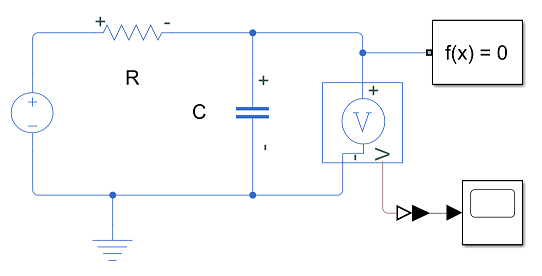

Abbildung 2: RC Schaltung

**PT1-Glied:**

0 = u - uC - uR

uC = y

uR = i * R

uC' = 1 / C * i

i = uC' * C

uR = uC' * C * R

0 = u - uC - uC' * C * R

0 = u - y - y' * C * R

u = R * C * y' + y

Laplace-Trafo:

U = T * s * Y + Y

U = Y * (T * s + 1)

Y / U = 1 / (T * s + 1) = G

numerator21 = 1;
R21 = 1000;
C21 = 0.0001;
T21 = R21 * C21;
denumerator21 = [T21, 1];
G21 = tf(numerator21, denumerator21);

T = 0,1

G = 1 / (T * s + 1)

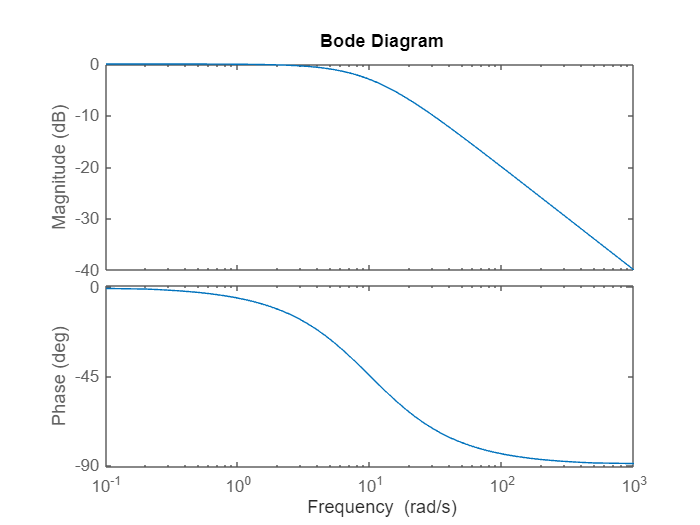

bode(G21);

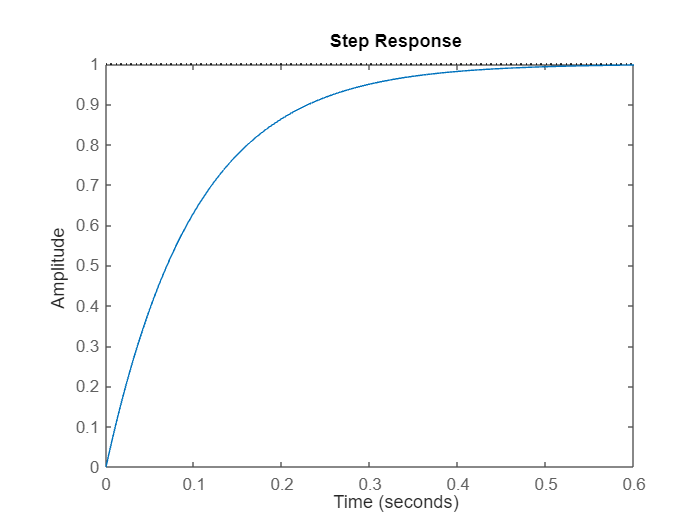

step(G21);

### 2)

Wiederholen Sie **1.3)** bis **1.5)** erneut mit R = $4.7k\Omega$ und vergleichen Sie die Sprungantworten.

Der Betrag der Polstellen steigt durch den höheren Widerstand, sodass die Übergangsfunktion eine höhere Steigung besitzt.

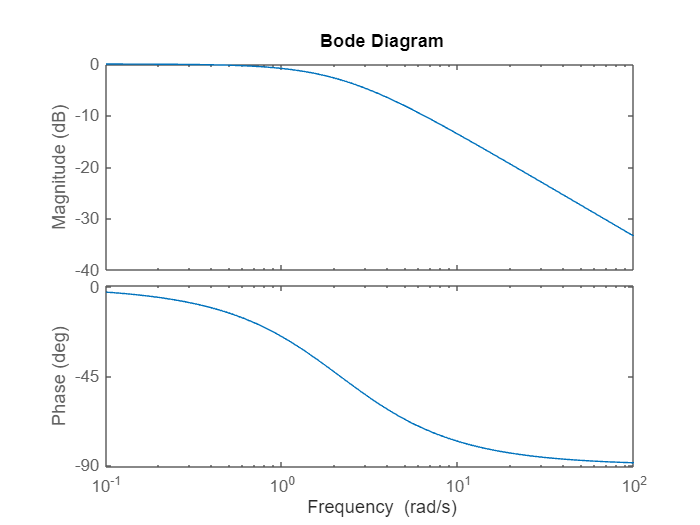

numerator22 = 1;
R22 = 4700;
C22 = 0.0001;
T22 = R22 * C22;
denumerator22 = [T22, 1];
G22 = tf(numerator22, denumerator22);
bode(G22);

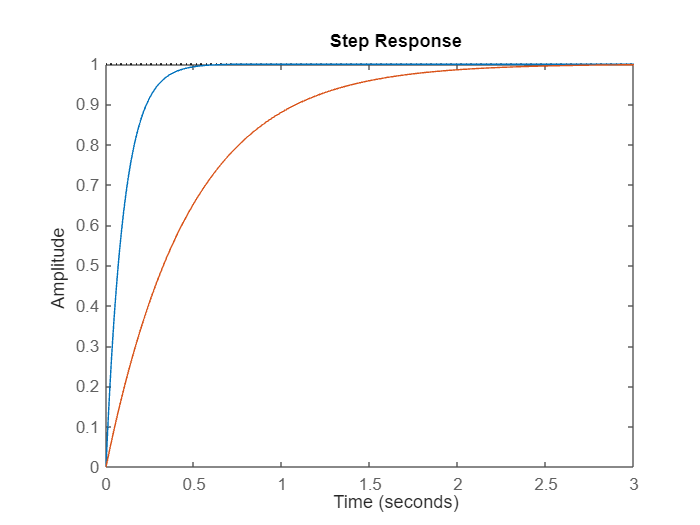


step(G21);
hold on;
step(G22);
hold off;

## Aufgabe 3

### 1)

Wiederholen Sie **Aufgabe 1.1** bis **1.3** für die Messschaltung aus Abb. 3 mit R1 = $100\Omega$, C1 = $1mF$, R2 = $1k\Omega$ und C2 = $1mF$. Beachten Sie, dass Sie bei **1.4)** die Parameter nicht mehr an der Sprungantwort ablesen können.

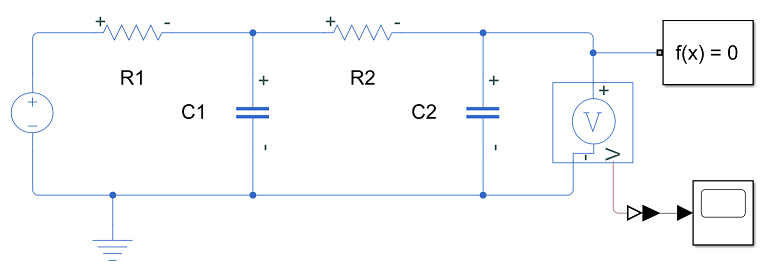

Abbildung 3: RC Tiefpass 2. Grades

**gekoppelte PT1-Glieder -> PT2-Glied**

### 2)

Bestimme Sie die Parameter für den ausgewählten Typ der Strecke rechnerisch mithilfe der Gleichungen, die Sie aus den Grundlagen der Elektrotechnik kennen. Da R1 ≪ R2, kann das Gesamtsystem durch zwei in Serie geschaltete Einzelsysteme aus unabhängigen RC-Tiefpässen 1. Grades *angenähert* werden.

GR(s) = G2(s) * G1(s)

G1(s) = ks1 / (T1 * s + 1)

G2(s) = ks2 / (T2 * s + 1)

numerator31 = 1;
R31 = 100;
C31 = 0.001;
T31 = R31 * C31;
denumerator31 = [T31, 1];
G31 = tf(numerator31, denumerator31);

numerator32 = 1;
R32 = 1000;
C32 = 0.001;
T32 = R32 * C32;
denumerator32 = [T32, 1];
G32 = tf(numerator32, denumerator32);

### 3)

Wiederholen Sie **1.5)** für die Messschaltung aus Abb. 3.

*Hinweis: Sie können die Gesamtübertragungsfunktion von zwei seriellen Übertragungsfunktion mit *`series`* bestimmen.*

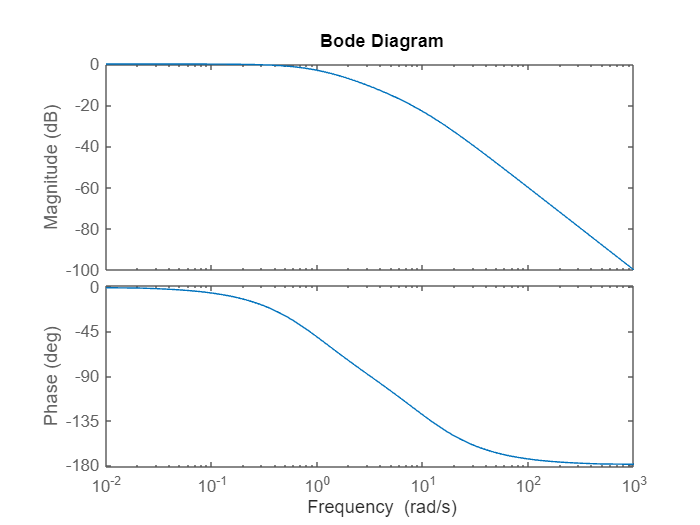

GR1 = series(G31, G32);
bode(GR1);

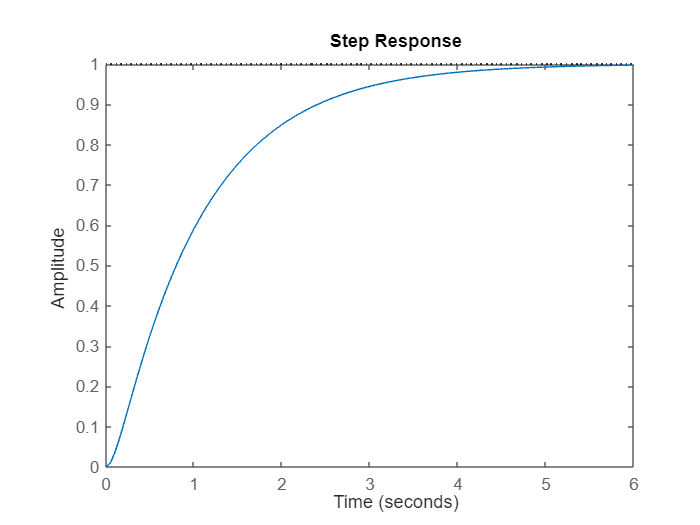

step(GR1);

### 4)

Wiederholen Sie **1.3),** **3.2)** und **1.5)** erneut mit C2 = $0.1mF$ und vergleichen Sie die Sprungantworten.

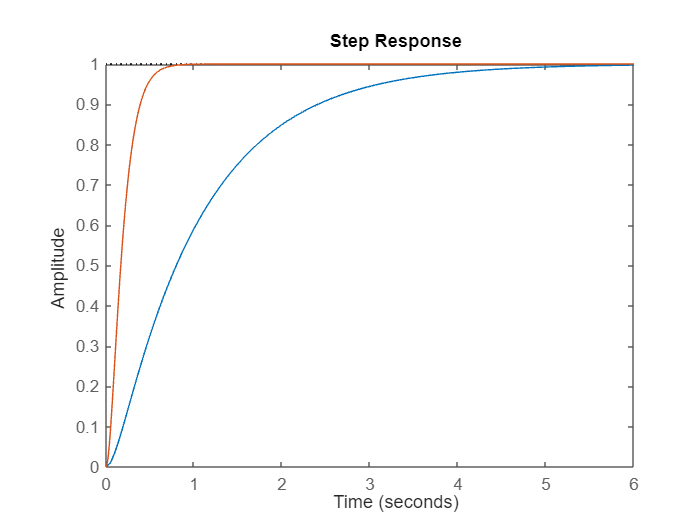

numerator311 = 1;
R311 = 100;
C311 = 0.001;
T311 = R311 * C311;
denumerator311 = [T311, 1];
G311 = tf(numerator311, denumerator311);

numerator322 = 1;
R322 = 1000;
C322 = 0.0001;
T322 = R322 * C322;
denumerator322 = [T322, 1];
G322 = tf(numerator322, denumerator322);

GR2 = series(G311, G322);
step(GR1);
hold on;
step(GR2);
hold off;

## Aufgabe 4

### 1)

Wiederholen Sie **Aufgabe 1** für die Messschaltung aus Abb. 4 mit R1 = $1k\Omega$, C1 = $100\mu F$ und L = $500H$. Beachten Sie bei **1.4)**, dass Sie die Parameter nicht mehr aus der Sprungantwort ablesen können.

*Hinweis: Es wurde zusätzlich ein "Inductor" verwendet.*

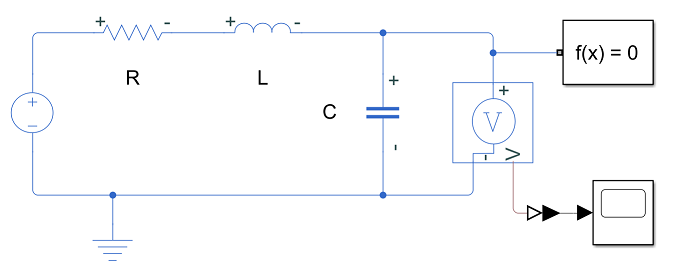

Abbildung 4: RLC Schwingkreis

**PT2-Glied**

### 2)

Wiederholen Sie **1.3)** bis **1.5)** erneut jeweils mit R = $0.5k\Omega$ Und R = $10k\Omega$ und vergleichen Sie die Sprungantworten.